clear;
close all;
clc;

%% Robot parameters
param = robot_parameters();

%% Initial state

q0 = [
    deg2rad(120);
    deg2rad(60)
];

dq0 = [
    0;
    0
];

x0 = [
    q0;
    dq0
];

%% Simulation settings

tspan = [0, 2.0];

options = odeset( ...
    'RelTol', 1e-8, ...
    'AbsTol', 1e-10, ...
    'MaxStep', 1e-3);

%% Run simulation

[t, x] = ode45( ...
    @(t, x) forward_dynamics_MC(t, x, param), ...
    tspan, ...
    x0, ...
    options);

%% Extract states

q  = x(:, 1:2);
dq = x(:, 3:4);

number_of_samples = length(t);

%% Allocate log arrays

ddq   = zeros(number_of_samples, 2);
tau   = zeros(number_of_samples, 2);
c_log = zeros(number_of_samples, 2);

kinetic_energy = zeros(number_of_samples, 1);

%% Recalculate dynamics at each output time

for k = 1:number_of_samples

    q_k  = q(k, :).';
    dq_k = dq(k, :).';

    %% Mass matrix
    M_k = mass_matrix(q_k, param);

    %% Coriolis and centrifugal torque
    c_k = coriolis_torque(q_k, dq_k, param);

    %% Applied joint torque
    tau_k = applied_joint_torque(t(k));

    %% Joint acceleration
    ddq_k = M_k \ (tau_k - c_k);

    %% Kinetic energy
    kinetic_energy(k) = ...
        0.5 * dq_k.' * M_k * dq_k;

    %% Store values
    tau(k, :)   = tau_k.';
    c_log(k, :) = c_k.';
    ddq(k, :)   = ddq_k.';

end

%% Display final state

disp('Final joint angle [deg]');

Final joint angle [deg]


disp(rad2deg(q(end, :)));

  236.9798  231.2904




disp('Final joint velocity [rad/s]');

Final joint velocity [rad/s]


disp(dq(end, :));

   -0.8375    5.3394




disp('Final kinetic energy [J]');

Final kinetic energy [J]


disp(kinetic_energy(end));

    0.5943



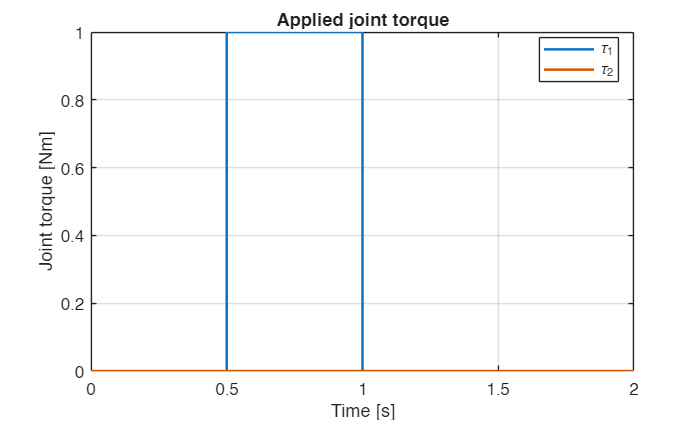


%% Applied joint torque

figure;

plot(t, tau(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, tau(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint torque [Nm]');

legend('\tau_1', '\tau_2', ...
    'Location', 'best');

title('Applied joint torque');

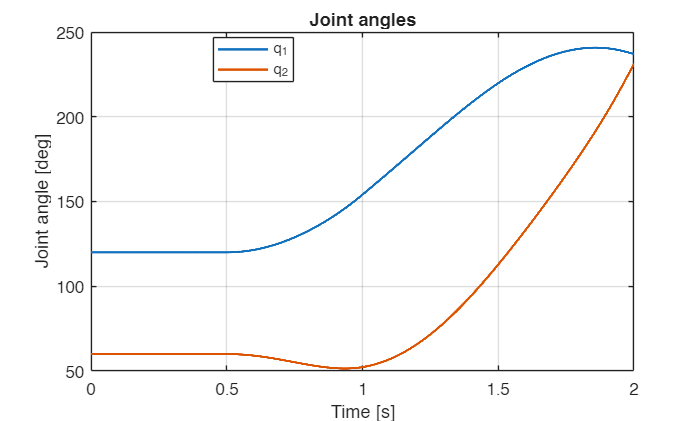


%% Joint angle

figure;

plot(t, rad2deg(q(:, 1)), 'LineWidth', 1.5);
hold on;
plot(t, rad2deg(q(:, 2)), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint angle [deg]');

legend('q_1', 'q_2', ...
    'Location', 'best');

title('Joint angles');

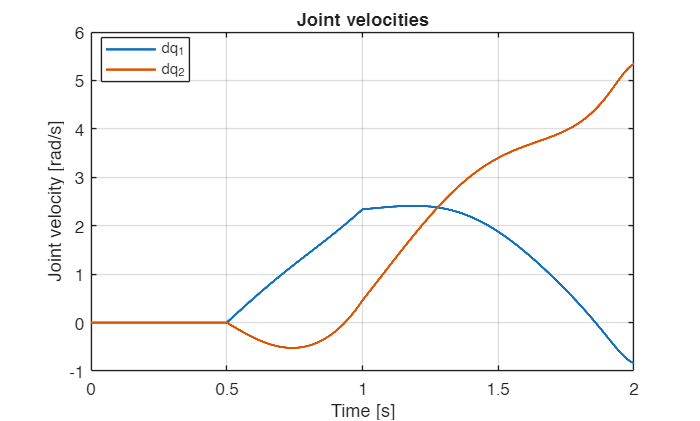


%% Joint velocity

figure;

plot(t, dq(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, dq(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint velocity [rad/s]');

legend('dq_1', 'dq_2', ...
    'Location', 'best');

title('Joint velocities');

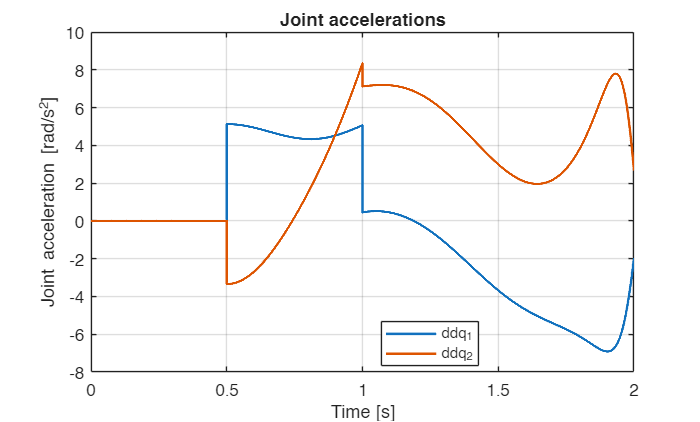


%% Joint acceleration

figure;

plot(t, ddq(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, ddq(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Joint acceleration [rad/s^2]');

legend('ddq_1', 'ddq_2', ...
    'Location', 'best');

title('Joint accelerations');

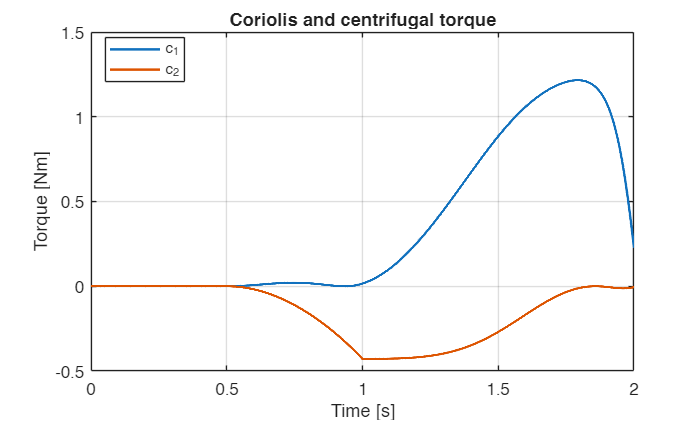


%% Coriolis and centrifugal torque

figure;

plot(t, c_log(:, 1), 'LineWidth', 1.5);
hold on;
plot(t, c_log(:, 2), 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Torque [Nm]');

legend('c_1', 'c_2', ...
    'Location', 'best');

title('Coriolis and centrifugal torque');

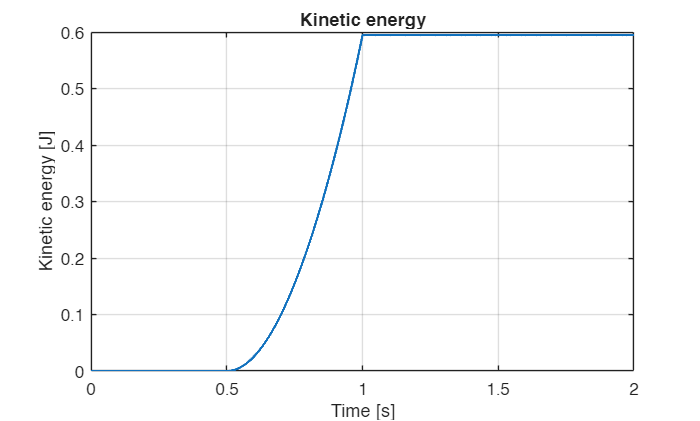


%% Kinetic energy

figure;

plot(t, kinetic_energy, 'LineWidth', 1.5);

grid on;

xlabel('Time [s]');
ylabel('Kinetic energy [J]');

title('Kinetic energy');


%% Energy variation after torque is removed

free_motion_indices = t >= 1.0;

energy_after_input = ...
    kinetic_energy(free_motion_indices);

relative_energy_variation = ...
    (max(energy_after_input) - min(energy_after_input)) ...
    / mean(energy_after_input);

disp('Relative kinetic-energy variation after 1.0 s');

Relative kinetic-energy variation after 1.0 s


disp(relative_energy_variation);

   7.8136e-08





function tau = applied_joint_torque(t)
%APPLIED_JOINT_TORQUE Same torque profile as the dynamics function.

    if t >= 0.5 && t < 1.0
        tau = [
            1.0;
            0.0
        ];
    else
        tau = [
            0.0;
            0.0
        ];
    end

end